# CMSE 821: Numerical Differential Equations / Final Exam

Student: Jorge A. Martinez Ortiz

Date Due: 12.14.2023

## Tasks

Instantiate the Crystal-growth class that encapsulates the dynamics of dendritic crystal growth

% Define parameters
params = struct;
params.M        = 3000;
params.alpha    = 0.9;
params.epsilon  = 0.01;
params.gamma    = 10;
params.Tm       = 1;
params.K        = 1.6;
params.xlim     = [0 9];
params.ylim     = [0 9];
params.h        = 0.03;

% Instantiate class
cg = Crystal_growth(params,...
                    @(x,y) phi_initial_condition(x,y),...
                    @(x,y) T_initial_condition(x,y))

cg =   Crystal_growth with properties:

             M: 3000
         alpha: 0.9000
       epsilon: 0.0100
         gamma: 10
            Tm: 1
             K: 1.6000
             x: [301×301 double]
             y: [301×301 double]
             h: 0.0300
            sz: [301 301]
      T_naught: [301×301 double]
    phi_naught: [301×301 double]


### Task 1


$$\phi_0 = \frac{1}{2}\Big[1-\tanh \Big(\frac{r-0.25}{0.015}\Big)\Big] \eta$$


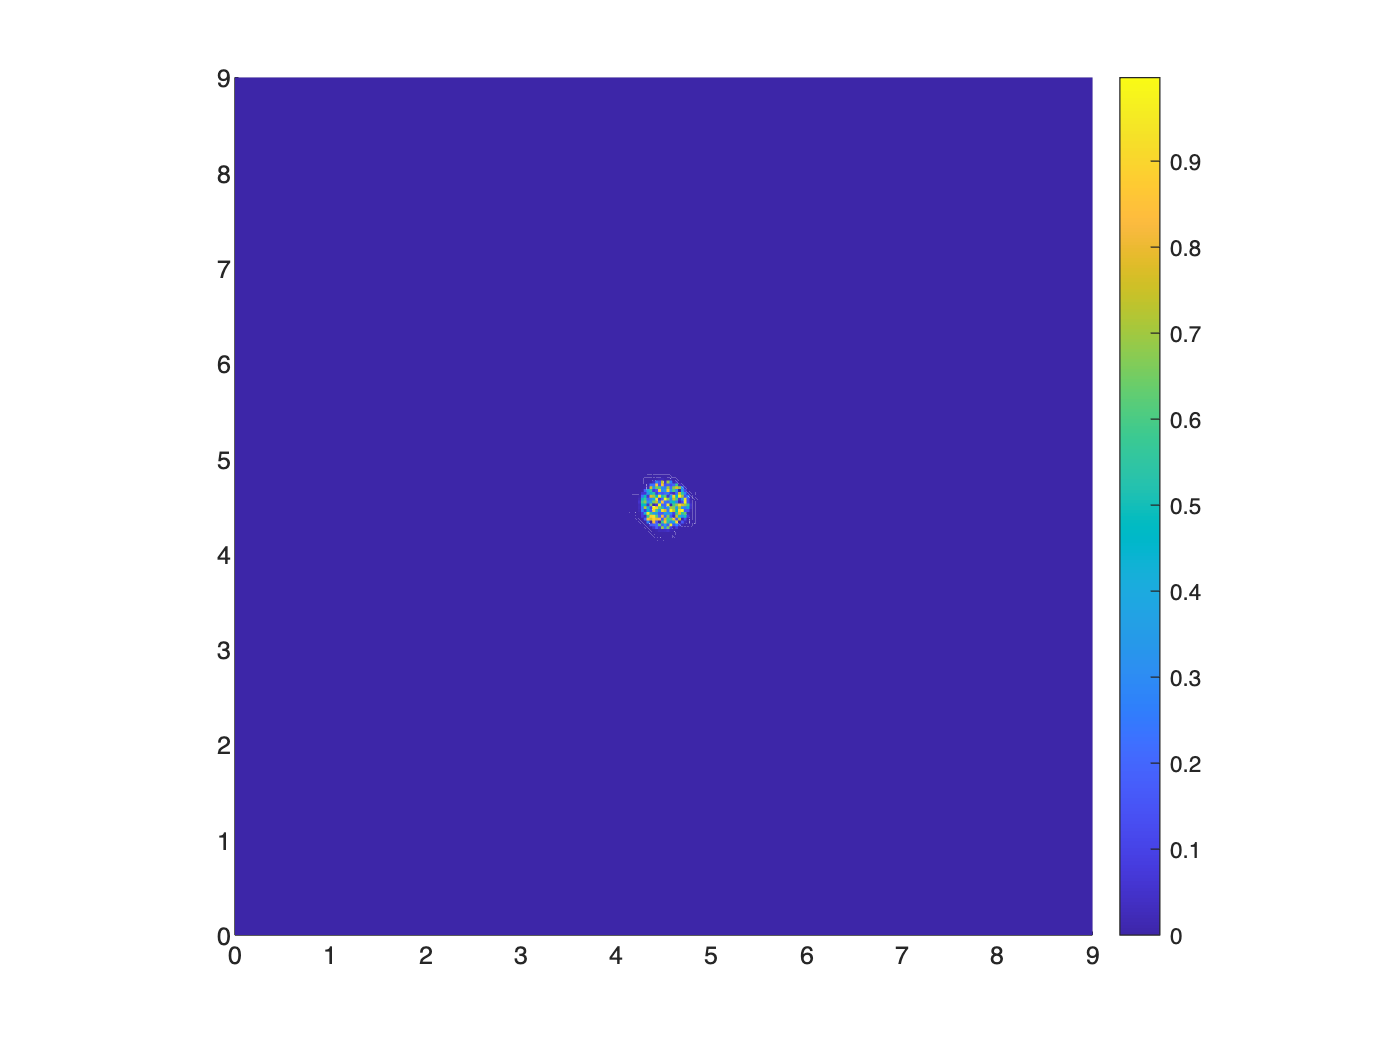

figure
fdraw(cg.x,cg.y,cg.phi_naught)

### Task 2

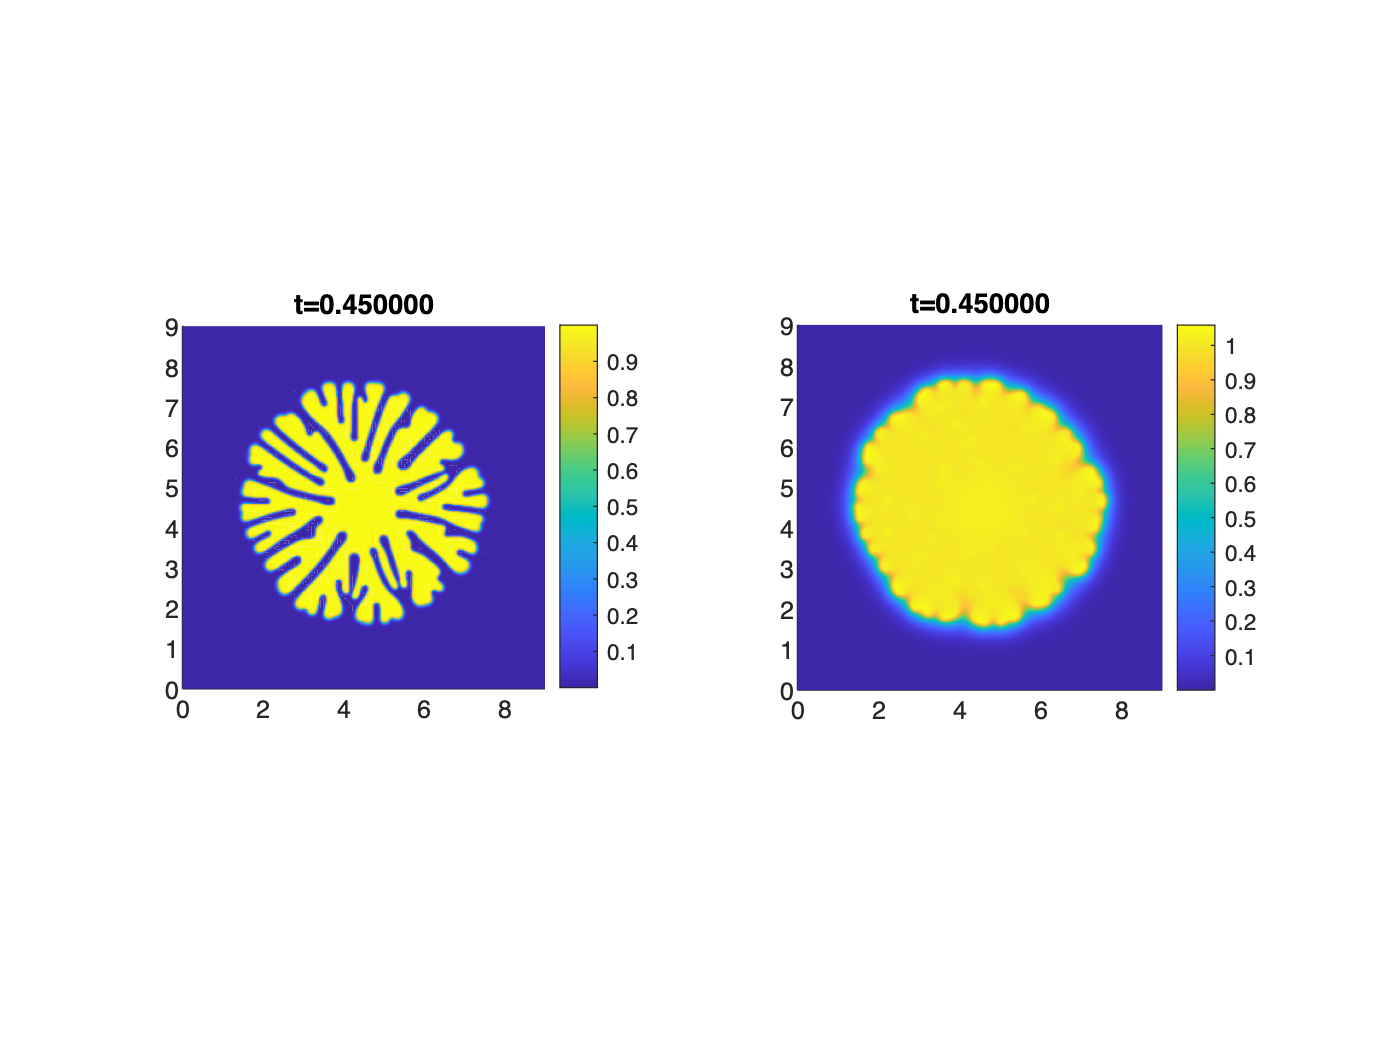

% Define run parameters
t_span  = [0 0.45];
k       = 0.0001;

figure
profile on
[phi,T] = animate(cg,t_span,k);

### Task 3

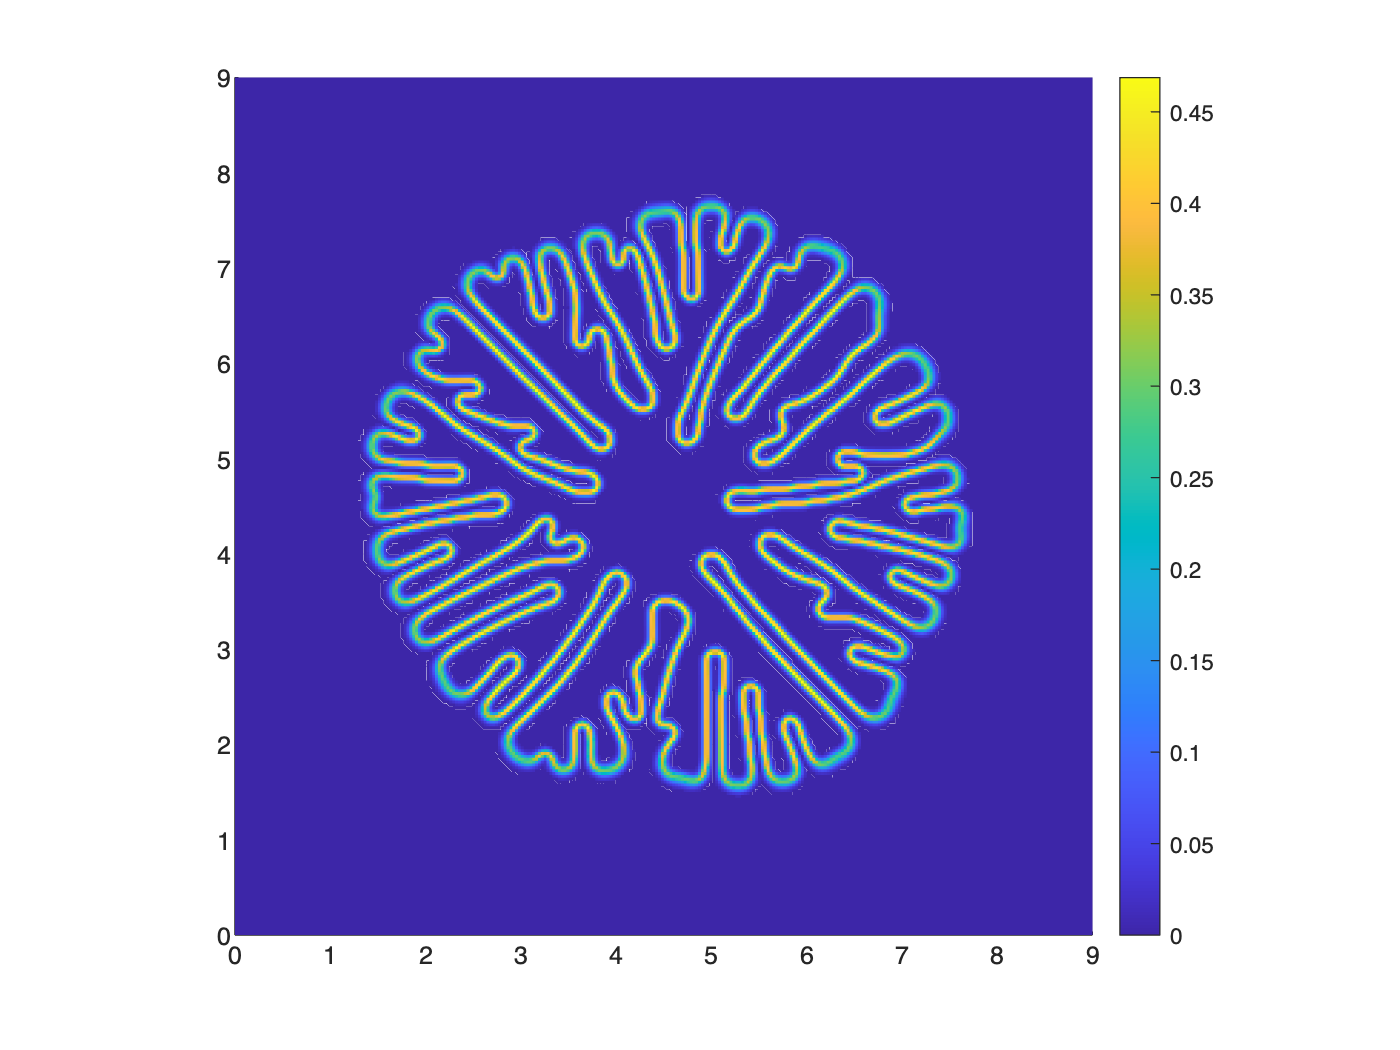

% Calculate gradient
[fx,fy,mag,idx] = grad(phi);

% Select points
mag(~idx) = 0;

% Draw magnitude of the gradient
figure
fdraw(cg.x,cg.y,mag);

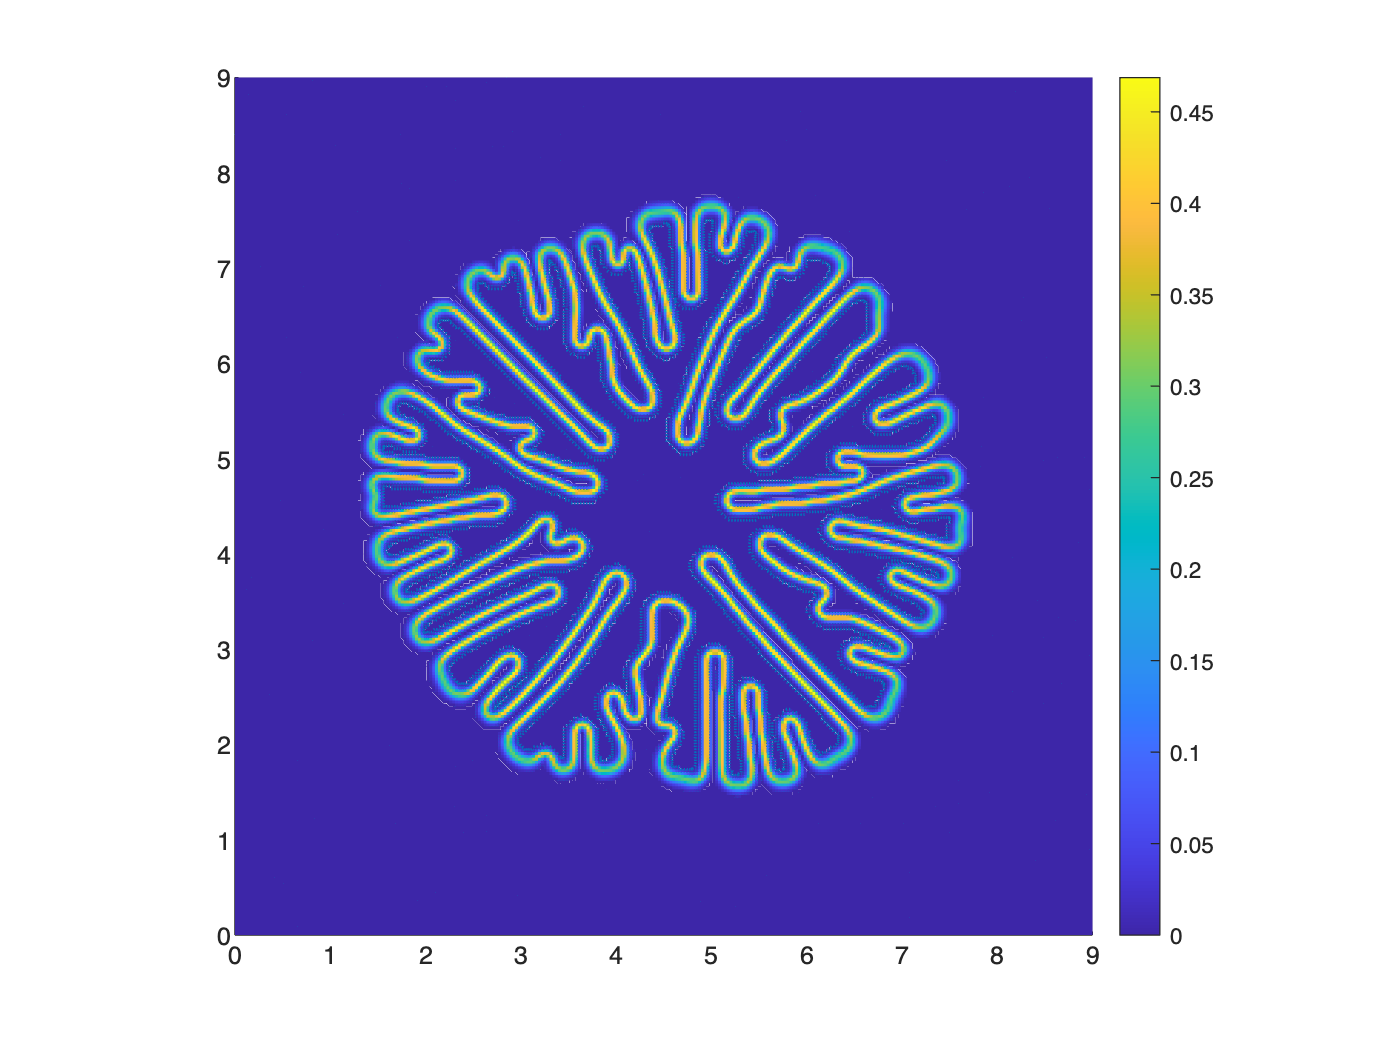

% Draw inward pointing vector
[theta,nx,ny] = inward_vector(phi);

figure
fdraw(cg.x,cg.y,mag)
hold on
quiver(cg.x,cg.y,nx,ny)

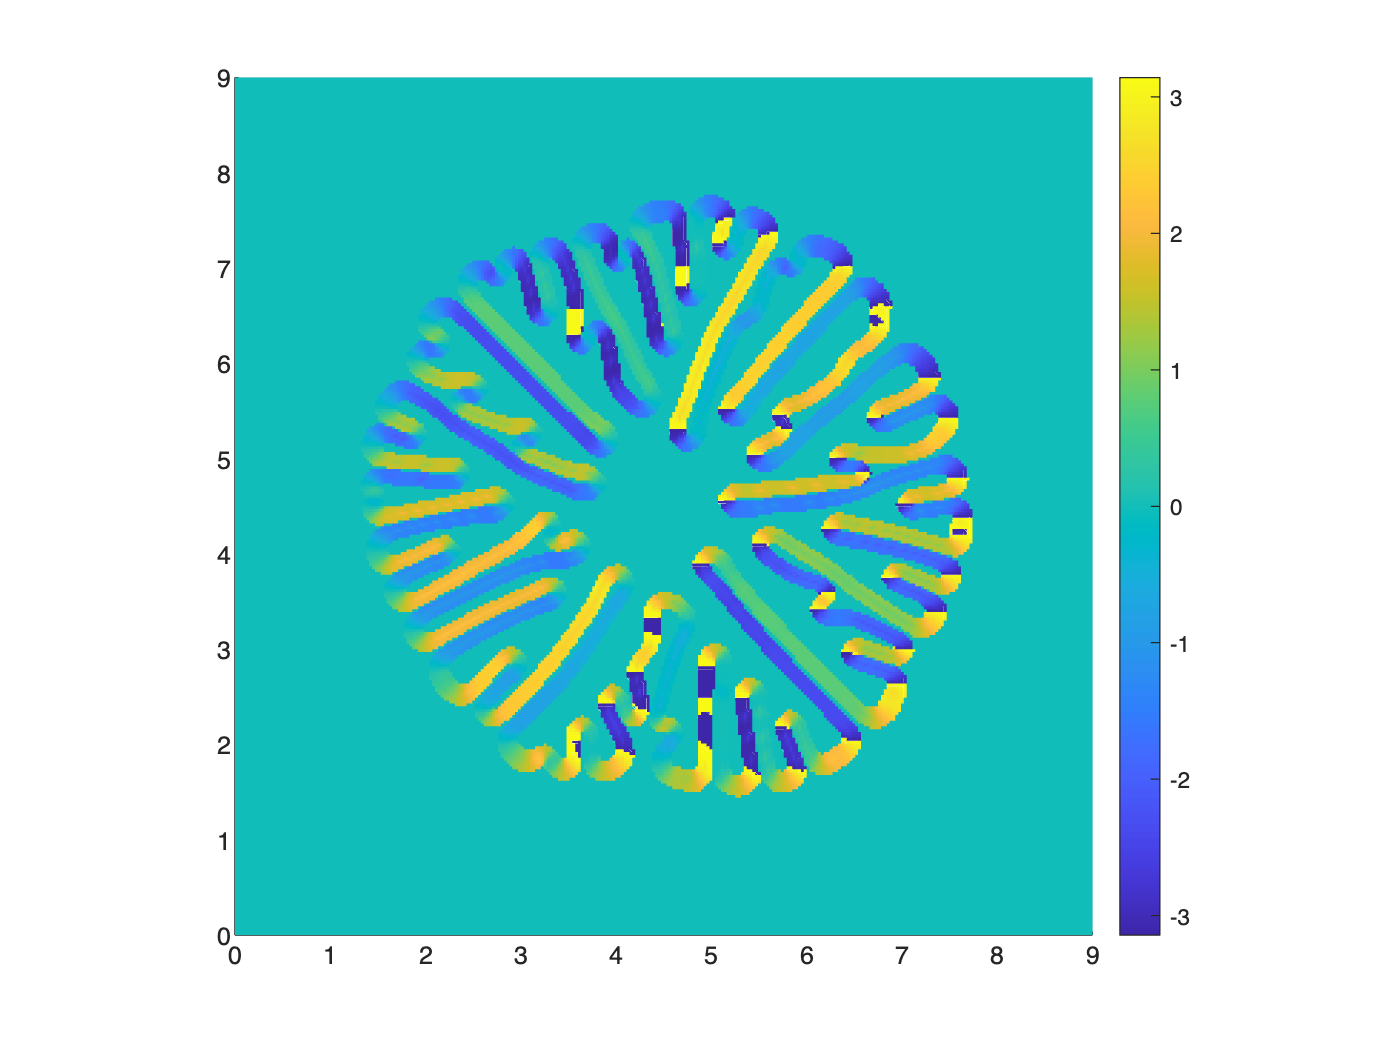

figure
fdraw(cg.x,cg.y,theta)

### Task 4

% Define scalar field parameters
epsilon         = 0.01;
delta           = 0.04;
s               = 6;
theta_naught    = 0.5;


% Define parameters
params = struct;
params.M        = 3000;
params.alpha    = 0.9;
params.epsilon  = @ (phi)   coefficient(phi,...
                                        epsilon,...
                                        delta,...
                                        s,...
                                        theta_naught);
params.gamma    = 10;
params.Tm       = 1;
params.K        = 1.6;
params.xlim     = [0 9];
params.ylim     = [0 9];
params.h        = 0.03;

% Instantiate class
cg = Crystal_growth(params,...
                    @(x,y) phi_initial_condition(x,y),...
                    @(x,y) T_initial_condition(x,y))

cg =   Crystal_growth with properties:

             M: 3000
         alpha: 0.9000
       epsilon: @(phi)coefficient(phi,epsilon,delta,s,theta_naught)
         gamma: 10
            Tm: 1
             K: 1.6000
             x: [301×301 double]
             y: [301×301 double]
             h: 0.0300
            sz: [301 301]
      T_naught: [301×301 double]
    phi_naught: [301×301 double]


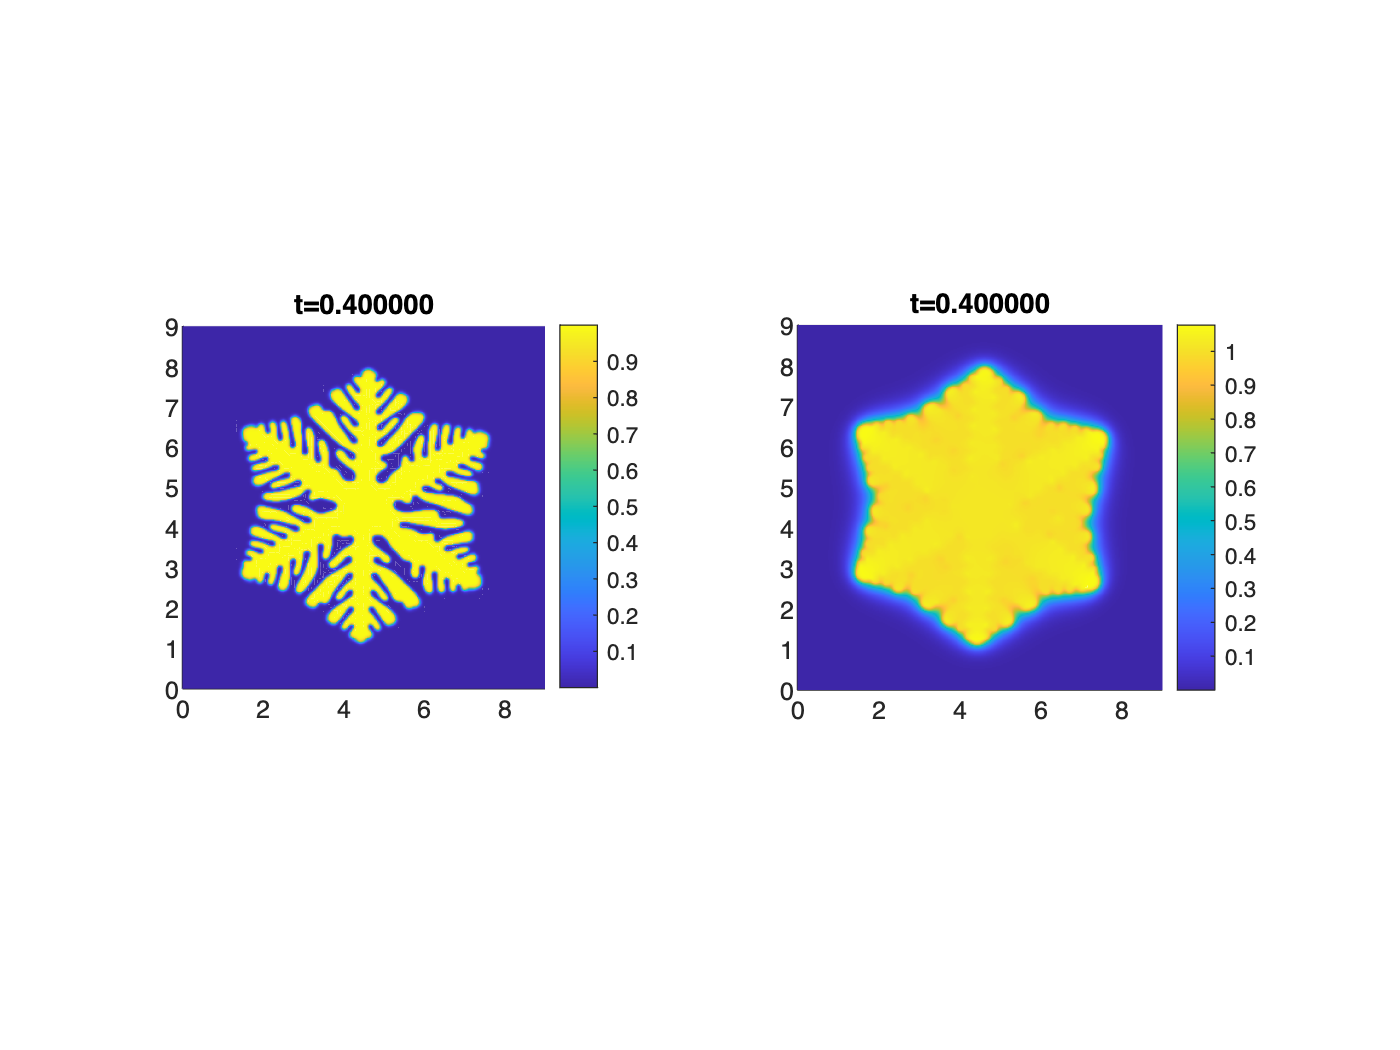


% Define run parameters
t_span  = [0 0.4];
k       = 0.0001;

figure
profile on
[phi,T] = animate(cg,t_span,k);

### Task 5

% Define scalar field parameters
epsilon         = 0.01;
delta           = 0.04;
s               = 6;
theta_naught    = 0.15;


% Define parameters
params = struct;
params.M        = 3000;
params.alpha    = 0.9;
params.epsilon  = @ (phi)   coefficient(phi,...
                                        epsilon,...
                                        delta,...
                                        s,...
                                        theta_naught);
params.gamma    = 10;
params.Tm       = 1;
params.K        = 1.6;
params.xlim     = [0 9];
params.ylim     = [0 9];
params.h        = 0.03;

% Instantiate class
cg = Crystal_growth(params,...
                    @(x,y) phi_initial_condition(x,y),...
                    @(x,y) T_initial_condition_nonuniform(x,y))

cg =   Crystal_growth with properties:

             M: 3000
         alpha: 0.9000
       epsilon: @(phi)coefficient(phi,epsilon,delta,s,theta_naught)
         gamma: 10
            Tm: 1
             K: 1.6000
             x: [301×301 double]
             y: [301×301 double]
             h: 0.0300
            sz: [301 301]
      T_naught: [301×301 double]
    phi_naught: [301×301 double]


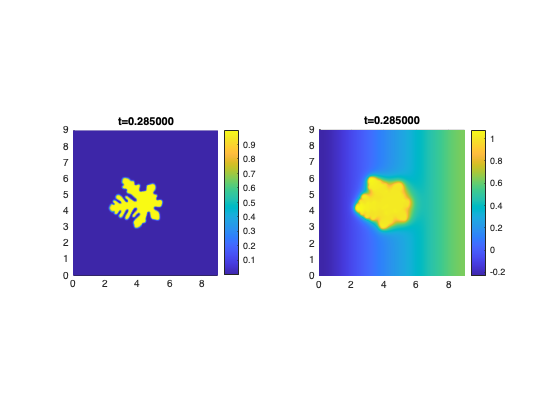


% Define run parameters
t_span  = [0 0.3];
k       = 0.0001;

figure
profile on
[phi,T] = animate(cg,t_span,k);

### Task 6

% Define scalar field parameters
epsilon         = 0.01;
delta           = 0.04;
s               = 4;
theta_naught    = 0.5;

% Define parameters
params = struct;
params.M        = 3000;
params.alpha    = 0.9;
params.epsilon  = @ (phi)   coefficient(phi,...
                                        epsilon,...
                                        delta,...
                                        s,...
                                        theta_naught);
params.gamma    = 10;
params.Tm       = 1;
params.K        = 1.6;
params.xlim     = [0 9];
params.ylim     = [0 9];
params.h        = 0.03;

% Define new stencils
five_pt         = [0  1  0;
                   1 -4  1;
                   0  1  0];

off_diag        = [1  0  1;
                   0 -4  0;
                   1  0  1];

six_pt_x        = [-1 0  1;
                   -2 0  2;
                   -1 0  1];

six_pt_y        = [-1 -2 -1;
                    0  0  0;
                    1  2  1];

mask.lap        = 2/3 * five_pt + 1/6 * off_diag;
mask.dx         = 1/8 * six_pt_x;
mask.dy         = 1/8 * six_pt_y;


% Instantiate class
cg = Crystal_growth(params,...
                    @(x,y) phi_initial_condition(x,y),...
                    @(x,y) T_initial_condition(x,y),...
                    mask)

cg =   Crystal_growth with properties:

             M: 3000
         alpha: 0.9000
       epsilon: @(phi)coefficient(phi,epsilon,delta,s,theta_naught)
         gamma: 10
            Tm: 1
             K: 1.6000
             x: [301×301 double]
             y: [301×301 double]
             h: 0.0300
            sz: [301 301]
      T_naught: [301×301 double]
    phi_naught: [301×301 double]


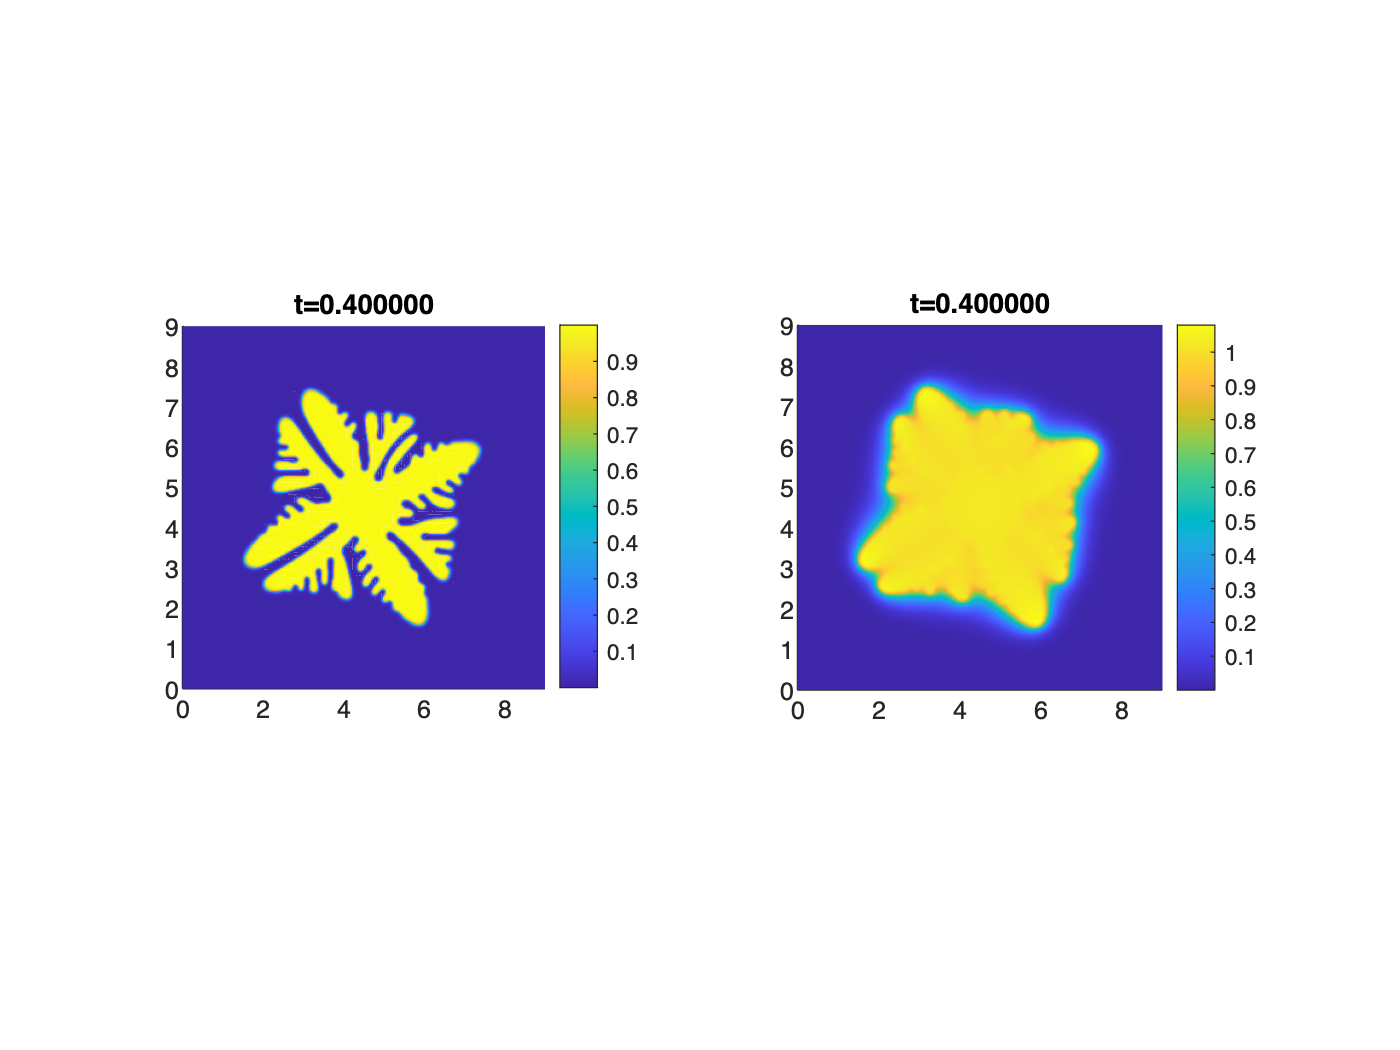

% Define run parameters
t_span  = [0 0.4];
k       = 0.0001;

figure
profile on
[phi,T] = animate(cg,t_span,k);

% Instantiate class
cg = Crystal_growth(params,...
                    @(x,y) phi_initial_condition(x,y),...
                    @(x,y) T_initial_condition_nonuniform(x,y),...
                    mask)

cg =   Crystal_growth with properties:

             M: 3000
         alpha: 0.9000
       epsilon: @(phi)coefficient(phi,epsilon,delta,s,theta_naught)
         gamma: 10
            Tm: 1
             K: 1.6000
             x: [301×301 double]
             y: [301×301 double]
             h: 0.0300
            sz: [301 301]
      T_naught: [301×301 double]
    phi_naught: [301×301 double]


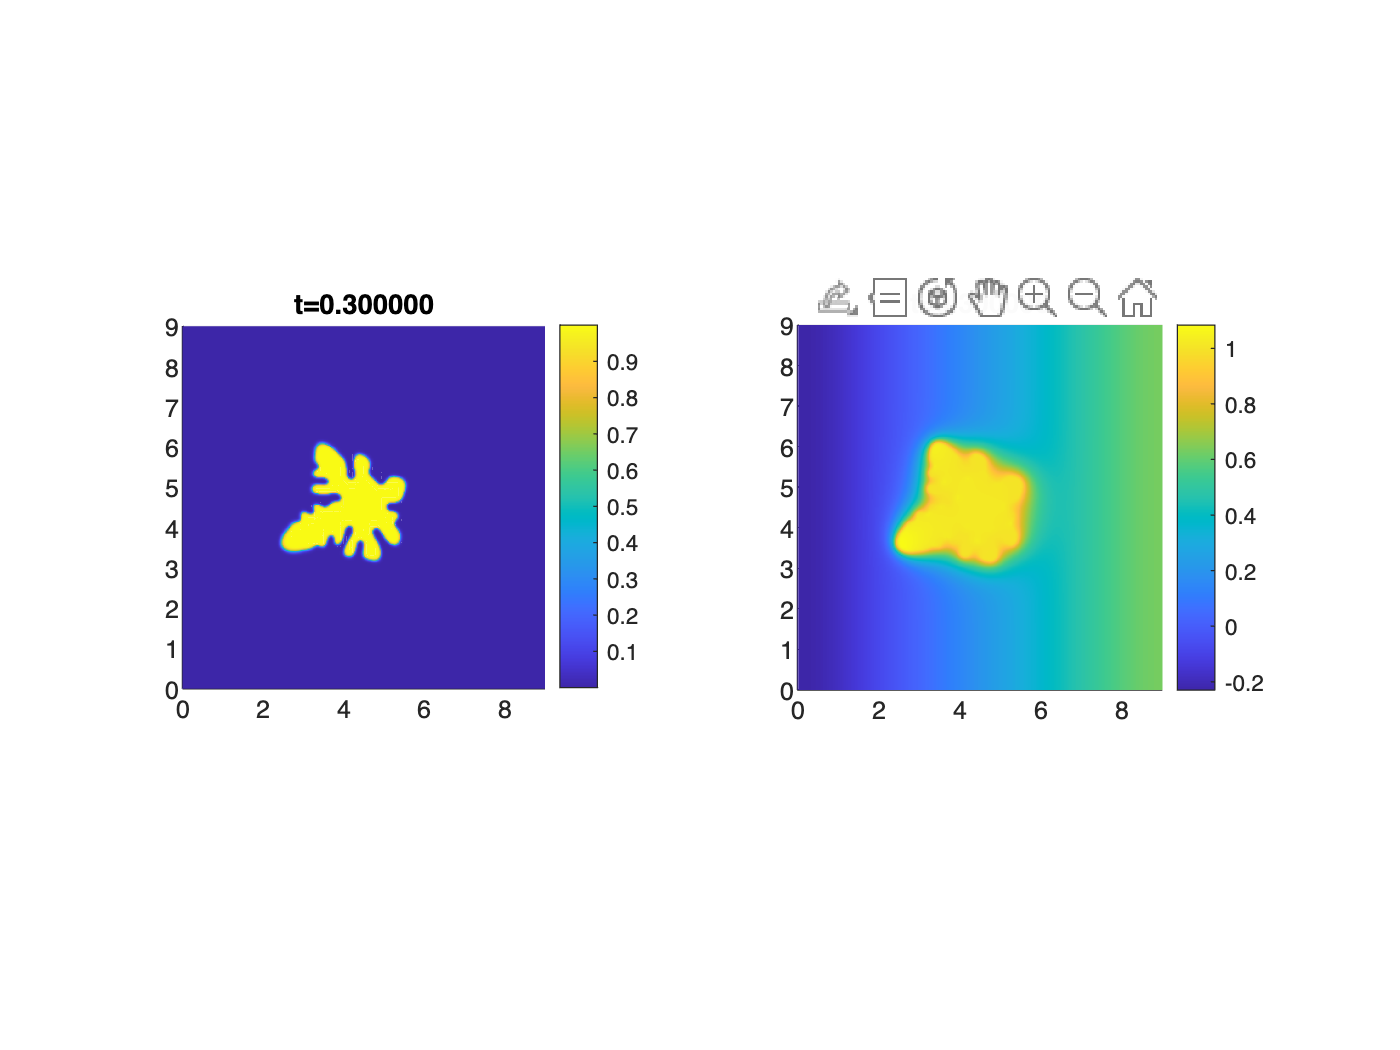


% Define run parameters
t_span  = [0 0.3];
k       = 0.0001;

figure
profile on
[phi,T] = animate(cg,t_span,k);

## Functions

function phi_naught = phi_initial_condition(x,y)
    %INITIAL_CONDITION Generates the initial condition to the
    %problem given the discretizations along the x and y 
    % directions
    theta = (hypot(x-4.5,y-4.5)-0.25)/0.015;
    phi_naught = 1/2 * (1 - tanh(theta)) .* rand(size(theta));
end

function T_naught = T_initial_condition(x,y)
    T_naught = zeros(size(x));
end

function T_naught = T_initial_condition_nonuniform(x,y)
    T_naught    = x/x(end,end) - 0.3;
end

function [g,g_prime] = coefficient(phi,epsilon,delta,s,theta_naught)
    theta = inward_vector(phi);

    % Calculate the phase
    phase = s * (theta - theta_naught);

    % Calculate the coefficient scalar field
    g       =  epsilon * (1 + delta * cos(phase));
    g_prime = -epsilon * delta * sin(phase);
end

function [fx,fy,mag,idx] = grad(f)
    [fx,fy] = gradient(f);

    mag = hypot(fx,fy);
    idx = mag > 0.01;
end

function [theta,nx,ny] = inward_vector(f)
    % Allocate memory
    nx      = zeros(size(f));
    ny      = zeros(size(f));
    theta   = zeros(size(f));

    % Calculate gradient
    [fx,fy,mag,idx] = grad(f);

    % Calculate inward vector
    nx(idx) = fx(idx) ./ mag(idx);
    ny(idx) = fy(idx) ./ mag(idx);
    
    % Calculate angle
    theta(idx) = atan2(ny(idx),nx(idx));
end